clc; clear; close all;

Loading test data:

data1 = load("data\data_1.mat");
data1.pendFirst.angle(1:round(0.12*250)) = [];
data1.pendFirst.time(1:round(0.12*250)) = [];
data1.pendFirst.angle =data1.pendFirst.angle(:) - data1.pendFirst.angle(1)

data1 = struct with fields:
    pendFirst: [1×1 struct]


data1.pendFirst.time =data1.pendFirst.time(:) - data1.pendFirst.time(1)

data1 = struct with fields:
    pendFirst: [1×1 struct]



data2 = load("data\data_2.mat");
data3 = load("data\data_3.mat");
data4 = load("data\data_4.mat");


 Parameters for matematical model

l_B = 0.132; % [m] Base langth. 13.2cm measured. 
l_P = 0.21; % [m] Pendulum length. 24cm measured.
I_B = 2*(1/12)*0.05*0.25^2; % [kg*m^2]Base, motor ang gerbox inertia (about mass centre)
I_P = (1/3)*0.010*0.25^2*1; % [kg*m^2] Pendulum inertia (about mass centre). Estimated with mass = 10g
m_P = 0.026 * 1; % [kg] Pendulum mass. 26g measured
B_B = -0.18;%0.01; % [Nm*rad/s] Motor friction.
B_P = -0.00048; % [Nm*rad/s] Penulum friction.
g = 9.81; % [m/s^2] gravity.

L = 1.3/1000; % [Henry] Motor inductance. From random data sheet
R = 4.2; % [Omh] Motor resistance. From random data sheet
K_t = 0.047; % [Nm/A] Motor tourqe constant. From random data sheet
K_e = 0.048; % [V/(rad/s)] Motor back EMF constant. From random data sheet

 LQR


A_lqr = [
    0, 1, 0, 0, 0; 
    (g*m_P*(m_P*l_B^2 + I_B))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), (B_P*(m_P*l_B^2 + l_P*m_P*l_B + I_B))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), 0, -(B_B*l_B*l_P*m_P)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), -(K_t*l_B*l_P*m_P)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P); 
    0, 0, 0, 1, 0; 
    -(g*l_B*l_P*m_P^2)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), -(B_P*(m_P*l_P^2 + l_B*m_P*l_P + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), 0, (B_B*(m_P*l_P^2 + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), (K_t*(m_P*l_P^2 + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P); 
    0, 0, 0, -K_e/L, -R/L]

A_lqr = 1.0e+03 *

         0    0.0010         0         0         0
    0.3105   -0.0010         0    0.1621   -0.0423
         0         0         0    0.0010         0
   -0.2298    0.0012         0   -0.3048    0.0796
         0         0         0   -0.0369   -3.2308



B = [0; 0; 0; 0; 1/L];

Q_lqr = [100 0 0 0 0;
    0 10 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0
    0 0 0 0 1];

R_lqr = 0.5;

K_lqr = lqr(A_lqr, B, Q_lqr, R_lqr);

Creating function handler for functions, this setts the parameters. One with locked base and on with free base.

odeFunHandler_Locked = @(t, x) odeFun_BaseLock(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)

odeFunHandler_Locked = function_handle with value:
    @(t,x)odeFun_BaseLock(x,l_B,l_P,I_B,I_P,L,m_P,B_B,B_P,R,g,K_t,K_e,K_lqr,B)


odeFunHandler_Free = @(t, x) odeFun_BaseFree(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)

odeFunHandler_Free = function_handle with value:
    @(t,x)odeFun_BaseFree(x,l_B,l_P,I_B,I_P,L,m_P,B_B,B_P,R,g,K_t,K_e,K_lqr,B)


Simulate from -pi/2. Locked base.

disp(data1.pendFirst.description)

Dropped from 3 a clock, base locked


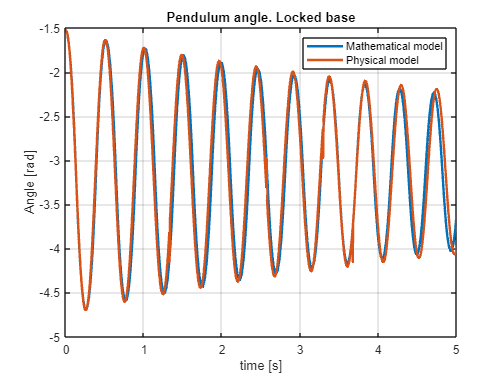

% For Runge-Kutta solver
tspan = [0 5];
% Initial condition
x0 = [
    -1.528;
    0;
    0;
    0;
    0];

%  Runge-Kutta solver
[t, x] = ode45(odeFunHandler_Locked, tspan, x0);

% Plotting:
plot(t, x(:, 1), LineWidth=2);
title('Pendulum angle. Locked base');
ylabel('Angle [rad]');
xlabel('time [s]');
hold on
plot(data1.pendFirst.time, data1.pendFirst.angle - pi/2+0.05,LineWidth=2);
xaxis([0 5])
legend('Mathematical model', 'Physical model');
grid on
box on
hold off

Simulate from pi/2. Locked base.

disp(data2.pendSecond.description)

Dropped from 9 a clock, base locked


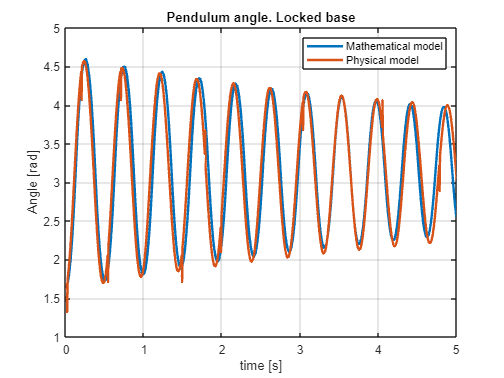

% For Runge-Kutta solver
tspan = [0 5];
% Initial condition
x0 = [
    1.63;
    0;
    0;
    0;
    0];

%  Runge-Kutta solver
[t, x] = ode45(odeFunHandler_Locked, tspan, x0);

% Plotting:
plot(t, x(:, 1), LineWidth=2);
title('Pendulum angle. Locked base');
ylabel('Angle [rad]');
xlabel('time [s]');
hold on
plot(data2.pendSecond.time, data2.pendSecond.angle + pi/2+0.05, LineWidth=2);
xaxis([0 5])
legend('Mathematical model', 'Physical model');
grid on
box on
hold off

Simulate from - pi/2. Base is free

disp(data3.pendThird.description)

Dropped from 3 a clock, base is free to move


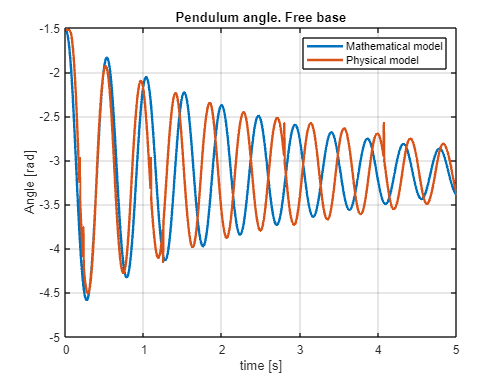

% For Runge-Kutta solver
tspan = [0 5];
% Initial condition
x0 = [
    -1.528;
    0;
    0;
    0;
    0];

%  Runge-Kutta solver
[t, x] = ode45(odeFunHandler_Free, tspan, x0);

% Plotting:
plot(t, x(:, 1), LineWidth=2);
title('Pendulum angle. Free base');
ylabel('Angle [rad]');
xlabel('time [s]');
hold on
plot(data3.pendThird.time, data3.pendThird.angle - pi/2+0.05,LineWidth=2);
xaxis([0 5])
legend('Mathematical model', 'Physical model');
grid on
box on
hold off

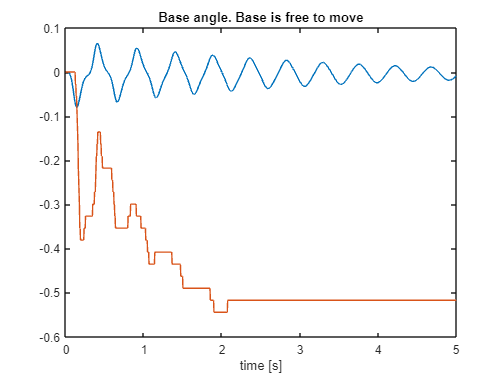



plot(t, x(:, 3))
title('\theta_b')
title('Base angle. Base is free to move')
xlabel('time [s]');
hold on
plot(data3.pendThird.time, data3.pendThird.baseAngle*(-1) -0.21788) %NB inverted
xaxis([0 5])
hold off

Simulate from - pi/2. Base is free

disp(data4.pendFourth.description)

Dropped from 9 a clock, base is free to move


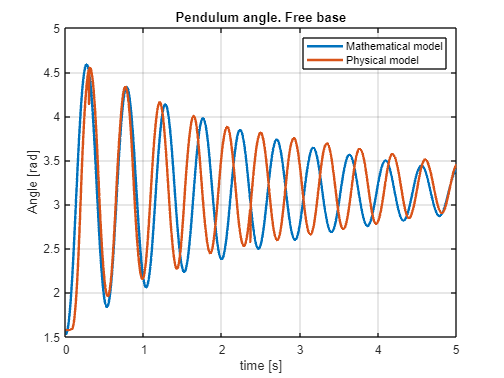

% For Runge-Kutta solver
tspan = [0 5];
% Initial condition
x0 = [
    1.528;
    0;
    0;
    0;
    0];

%  Runge-Kutta solver
[t, x] = ode45(odeFunHandler_Free, tspan, x0);

% Plotting:
plot(t, x(:, 1), LineWidth=2);
title('Pendulum angle. Free base');
ylabel('Angle [rad]');
xlabel('time [s]');
hold on
plot(data4.pendFourth.time, data4.pendFourth.angle + pi/2+0.05*0,LineWidth=2);
xaxis([0 5])
legend('Mathematical model', 'Physical model');
grid on
box on
hold off

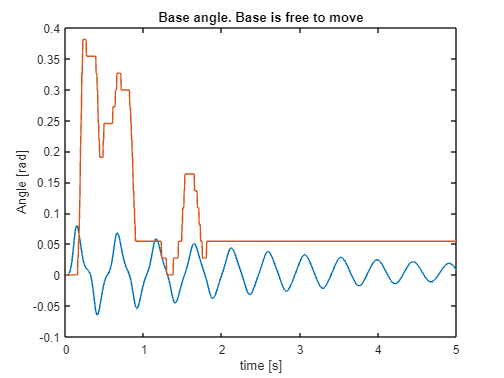



plot(t, x(:, 3))
title('Base angle. Base is free to move')
ylabel('Angle [rad]');
xlabel('time [s]');
hold on
plot(data4.pendFourth.time, data4.pendFourth.baseAngle*(-1) + 0.354) %NB inverted
xaxis([0 5])
hold off

function dxdt = odeFun_BaseLock(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)
    dxdt = [
    x(2); 
    -(B_P*x(2) + g*m_P*sin(x(1)) + l_P^2*m_P*cos(x(1))*sin(x(1))*x(4)^2 - (l_B*l_P*m_P*cos(x(1))*(- m_P*sin(2*x(1))*x(4)*l_P^2*x(2) + l_B*m_P*sin(x(1))*l_P*x(2)^2 - B_P*x(2) + B_B*x(4) + K_t*x(5)))/(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B))/((m_P*l_P^2 + I_P)*((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)); 
    x(4); 
    -(B_B*x(4) - B_P*x(2) + K_t*x(5) - l_P^2*m_P*sin(2*x(1))*x(4)*x(2) + l_B*l_P*m_P*sin(x(1))*x(2)^2 - (l_B*l_P*m_P*cos(x(1))*(m_P*cos(x(1))*sin(x(1))*l_P^2*x(4)^2 + B_P*x(2) + g*m_P*sin(x(1))))/(m_P*l_P^2 + I_P))/(((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)); 
    -(K_e*x(4) - 0 + R*x(5))/L
    ];
dxdt(5) = 0; % Setting current to 0
dxdt(3:4) = 0; % Locking base
end

function dxdt = odeFun_BaseFree(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)
    dxdt = [
    x(2); 
    -(B_P*x(2) + g*m_P*sin(x(1)) + l_P^2*m_P*cos(x(1))*sin(x(1))*x(4)^2 - (l_B*l_P*m_P*cos(x(1))*(- m_P*sin(2*x(1))*x(4)*l_P^2*x(2) + l_B*m_P*sin(x(1))*l_P*x(2)^2 - B_P*x(2) + B_B*x(4) + K_t*x(5)))/(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B))/((m_P*l_P^2 + I_P)*((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)); 
    x(4); 
    -(B_B*x(4) - B_P*x(2) + K_t*x(5) - l_P^2*m_P*sin(2*x(1))*x(4)*x(2) + l_B*l_P*m_P*sin(x(1))*x(2)^2 - (l_B*l_P*m_P*cos(x(1))*(m_P*cos(x(1))*sin(x(1))*l_P^2*x(4)^2 + B_P*x(2) + g*m_P*sin(x(1))))/(m_P*l_P^2 + I_P))/(((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)); 
    -(K_e*x(4) - 0 + R*x(5))/L
    ];
dxdt(5) = 0; % Setting current to 0
end